## IED TW delays VS NA XC delays

clc; clear; close all; addpath z_toolbox;
load(fullfile('step6_NAxcorr_polyfit', ...
    'NAnon6d0IED_XC100ms_polyfit_delays_Rmas_ED_es.mat'), ...
    'IEDtwDas', 'NAxcDas');
x = IEDtwDas; y = NAxcDas;
[forest, ~, scores] = iforest([x, y], "ContaminationFraction", 0.1);
x = x(scores <= forest.ScoreThreshold);
y = y(scores <= forest.ScoreThreshold);
[~, Curve, ~] = f_polyfit(x, y, 1);
[R, P] = corr(x, y, 'type', 'Spearman');
figure('Units', 'centimeters', 'Position', [5, 5, 12, 10]);
f_densityScatter(x, y, 6); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(x)-1, max(x)+1]); ylim([min(y)-1, max(y)+1]);
xlabel('IED-TW Delay (ms)'); ylabel('NA-LC Delay (ms)');
disp(['r = ', num2str(R), ' p=', num2str(P)]);

r = 0.23789 p=0


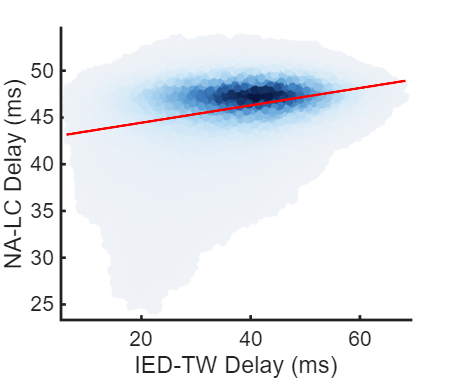

set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## Euclidean distance vs. NA XC delays

clc; clear; close all;
load(fullfile('step6_NAxcorr_polyfit', ...
    'NAnon6d0IED_XC100ms_polyfit_delays_Rmas_ED_as.mat'), ...
    'adjR2_xcDED_as');
[~, order_opt] = max(mean(adjR2_xcDED_as, 1));
load(fullfile('step6_NAxcorr_polyfit', ...
    'NAnon6d0IED_XC100ms_polyfit_delays_Rmas_ED_es.mat'), ...
    'EDas', 'NAxcDas');
x = EDas; y = NAxcDas;
[forest, ~, scores] = iforest([x, y], "ContaminationFraction", 0.1);
x = x(scores <= forest.ScoreThreshold);
y = y(scores <= forest.ScoreThreshold);
[polyModel, Curve, Ftest] = f_polyfit(x, y, order_opt);
adjR2 = polyModel.adjR2; Fstat = Ftest.Fstat; p = Ftest.p_value;
figure('Units', 'centimeters', 'Position', [5, 5, 12, 10]);
f_densityScatter(x, y, 5); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(x)-1, max(x)+1]); ylim([min(y)-1, max(y)+1]);
xlabel('Euclidean Distance (mm)'); ylabel('NA-LC Delay (ms)');
disp(['adjR2 = ', num2str(adjR2), ' F=', num2str(Fstat), ' p=', num2str(p)]);

adjR2 = 0.26849 F=17706.1367 p=0


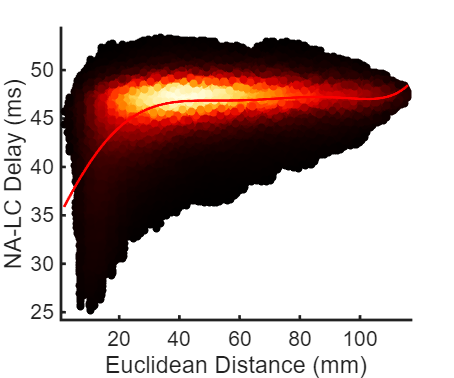

set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## NA XC strength vs delays

clc; clear; close all;
load(fullfile('step6_NAxcorr_polyfit', ...
    'NAnon6d0IED_XC100ms_polyfit_delays_Rmas_ED_es.mat'), ...
    'NAxcRas', 'NAxcDas');
x = NAxcRas; y = NAxcDas;
[forest, ~, scores] = iforest([x, y], "ContaminationFraction", 0.1);
x = x(scores <= forest.ScoreThreshold);
y = y(scores <= forest.ScoreThreshold);
[R, P] = corr(x, y, 'type', 'Spearman');
[~, Curve, ~] = f_polyfit(x, y, 1);
figure('Units', 'centimeters', 'Position', [5, 5, 12, 10]);
f_densityScatter(x, y, 5); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(x)-0.01, max(x)+0.01]); ylim([min(y)-1, max(y)+1]);
xlabel('log(NA-LC Strength)'); ylabel('NA-LC Delay (ms)');
disp(['r=', num2str(R), ' p=', num2str(P)]);

r=-0.25605 p=0


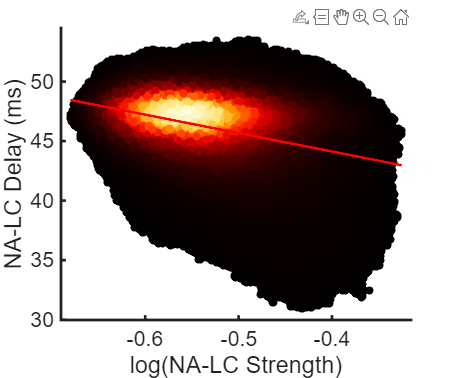

set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## Fiber count VS NA XC delays

clc;clear;close all;
load(fullfile('step6_NAxcorr_polyfit', ...
    'NAnon6d0IED_XC100ms_polyfit_delay_fibN.mat'), ...
    'fibNas', 'NAxcDas');
x = fibNas; y = NAxcDas;
[forest, tf, scores] = iforest([x, y], "ContaminationFraction", 0.1);
x = x(scores <= forest.ScoreThreshold);
y = y(scores <= forest.ScoreThreshold);
[R, P] = corr(x, y, 'type', 'Spearman');
[polyModel, Curve, Ftest] = f_polyfit(x, y, 1);
figure('Units', 'centimeters', 'Position', [5, 5, 12, 10]);
f_densityScatter(x, y, 5); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(x)-0.1, max(x)+0.1]);
ylim([min(y)-1, max(y)+1]);
xlabel('SC Strength'); ylabel('NA-LC Delay (ms)');
disp(['r=', num2str(R), ' p=', num2str(P)]);

r=-0.20545 p=0


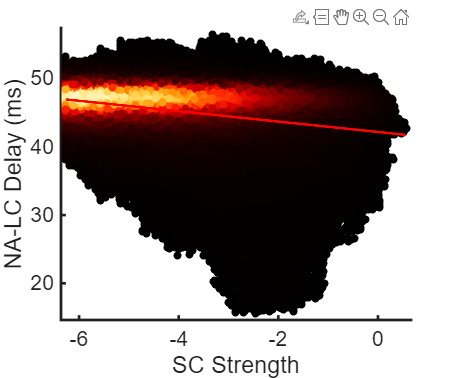

set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);